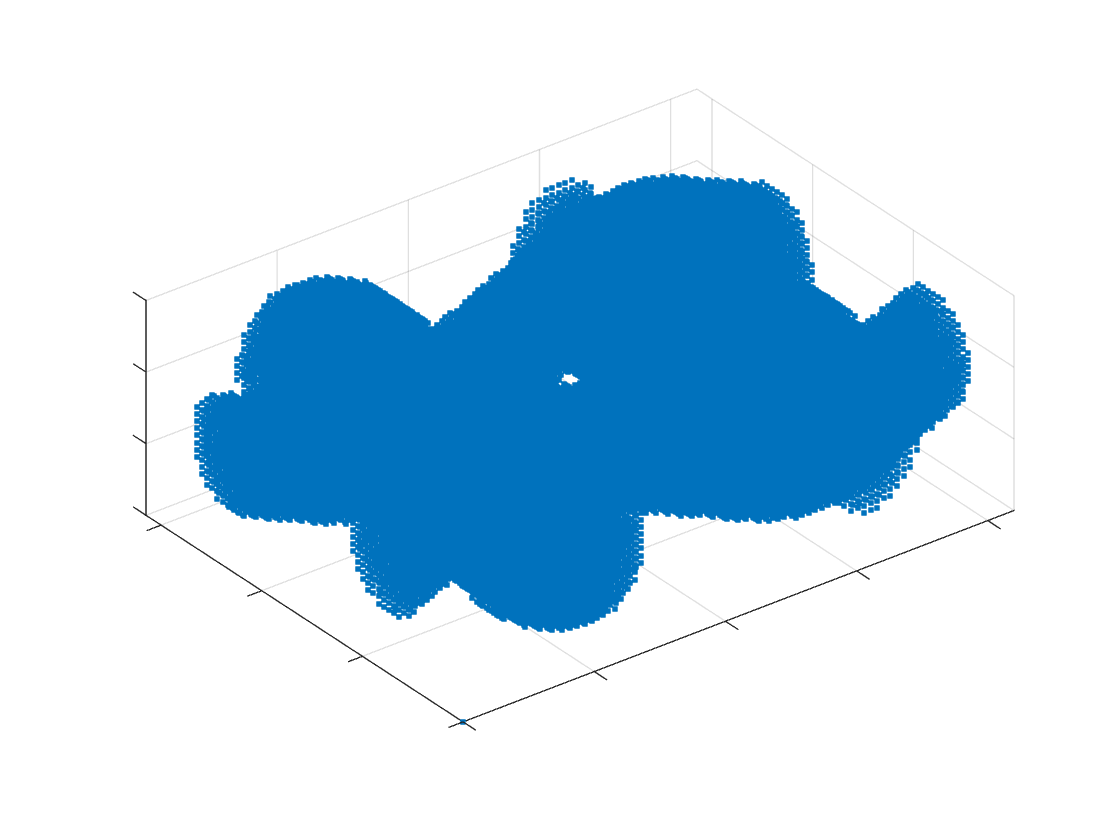

a = 1/3;
b = 1/4;
d = 0.06;
delta = 0.004;
theta_lat = deg2rad(19.8);
theta_lon = deg2rad(25.64);
substance = getSubstance(a,b,d,delta, theta_lat, theta_lon);
Size = size(substance);

point = zeros(200000, 3);
count = 1;
for i=1:Size(1)
    for j=1:Size(2)
        for k=1:Size(3)
            if substance(i, j, k) == 1
                point(count,:) = [i, j, k];
                count = count + 1;
            end
        end
    end
end             

figure
scatter3(point(:,3), point(:,2), point(:,1), '.')
set(gca, 'XTickLabel', []);
set(gca, 'YTickLabel', []);
set(gca, 'ZTickLabel', []);
axis equal;

result = zeros(10,1);
delta = logspace(-2, -1.5, 10);

for count = 1:10
    result(count) = calK_s(a,b,d,delta(count), theta_lat, theta_lon, 0.033);
end


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>



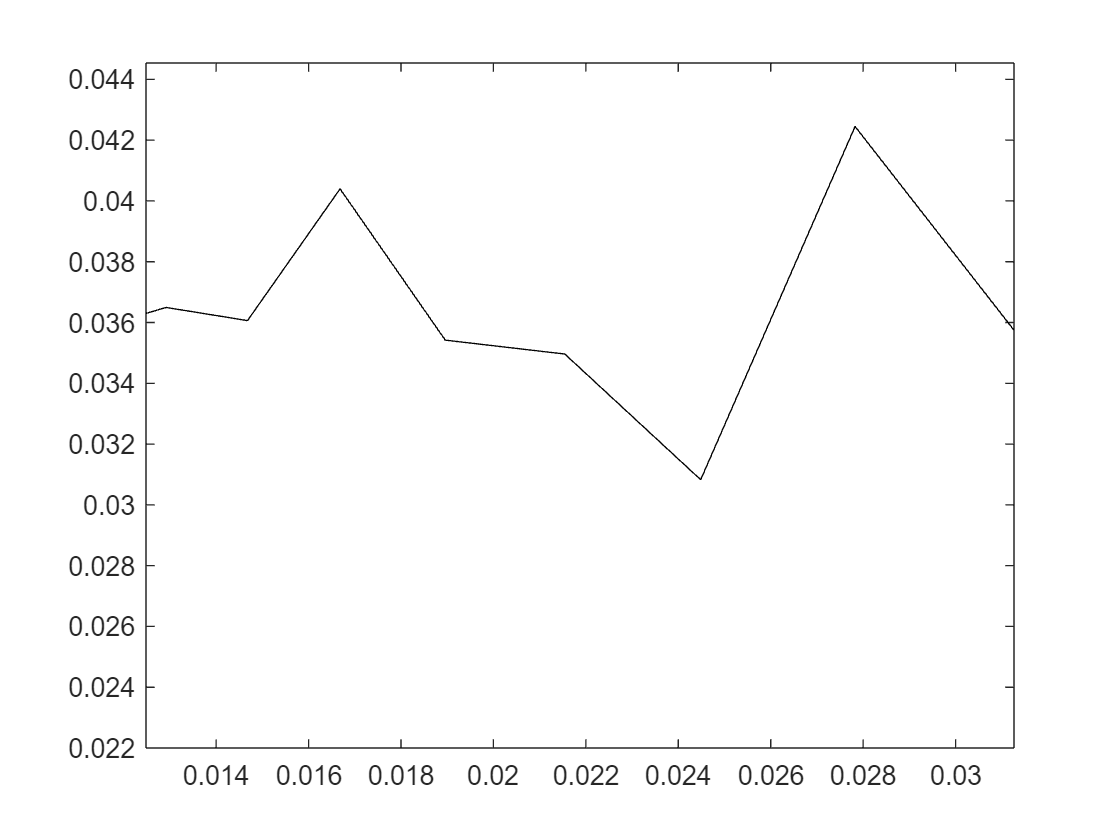


plot(delta, result, '-k')
ylim([0.02, 0.05])

mean(result)

ans = 0.0361

result = calK_s(a,b,d,delta, theta_lat, theta_lon, 0.033);


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>
